## Unit 4: Contact Modelling

Contact modelling is a challenging yet important aspect of robotics simulation. It has been utilised in the previous unit when modelling the interaction between the cylinder and ClawBot gripper: the blue environment block contains all of the contact modelling information.

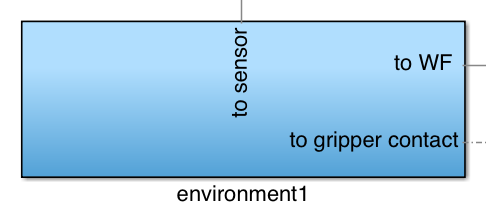     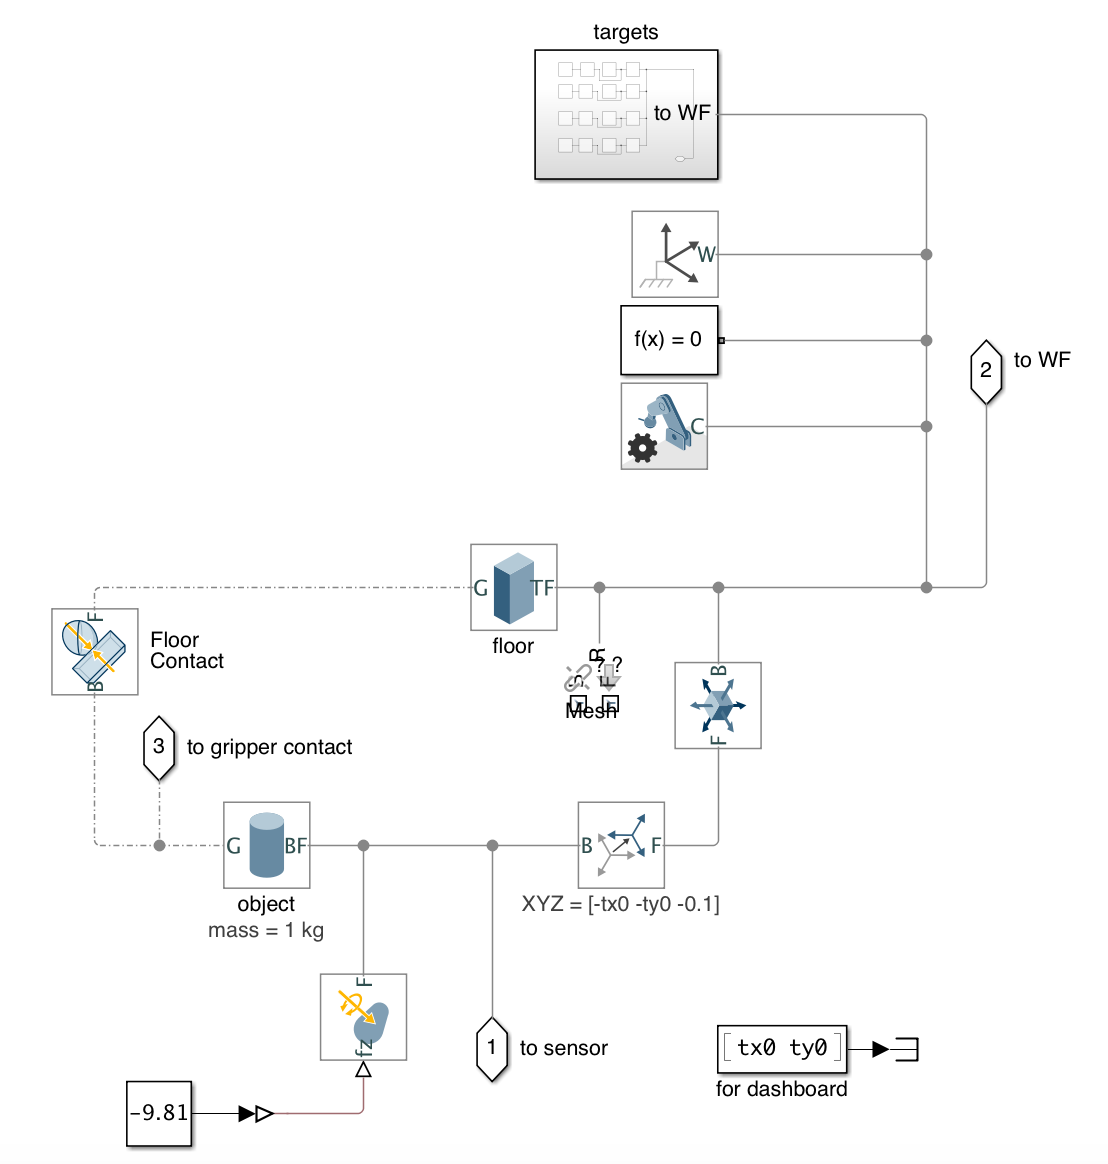

Contact modelling impact forces in Simscape Multibody involves simplifying the system to a **spring-mass-damper system**. The necessary stiffness and damping coefficients to prevent objects from penetrating each other can then be calculated. 

Setting the stiffness parameter higher than necessary can heavily affect the speed of your simulations, whilst setting it too low will result in the bodies visually penetrating each other, hence it is important to compute it correctly. 

The following sections are relevant for a single point of contact, as with the spherical gripper. The coefficients can be scaled and the necessary contact forces distributed to apply the theory to more points of contact, for example if using the block gripper.

### 4.1 Stiffness

In this context, the stiffness can be defined as k=F/d, where F is the force required to hold the object up, i.e. m*g, and d is the maximum penetration distance between objects. 

It simplifies calculations if you set the object to be a point mass (under the inertia tab), rather than the default which is calculating it by geometry. 

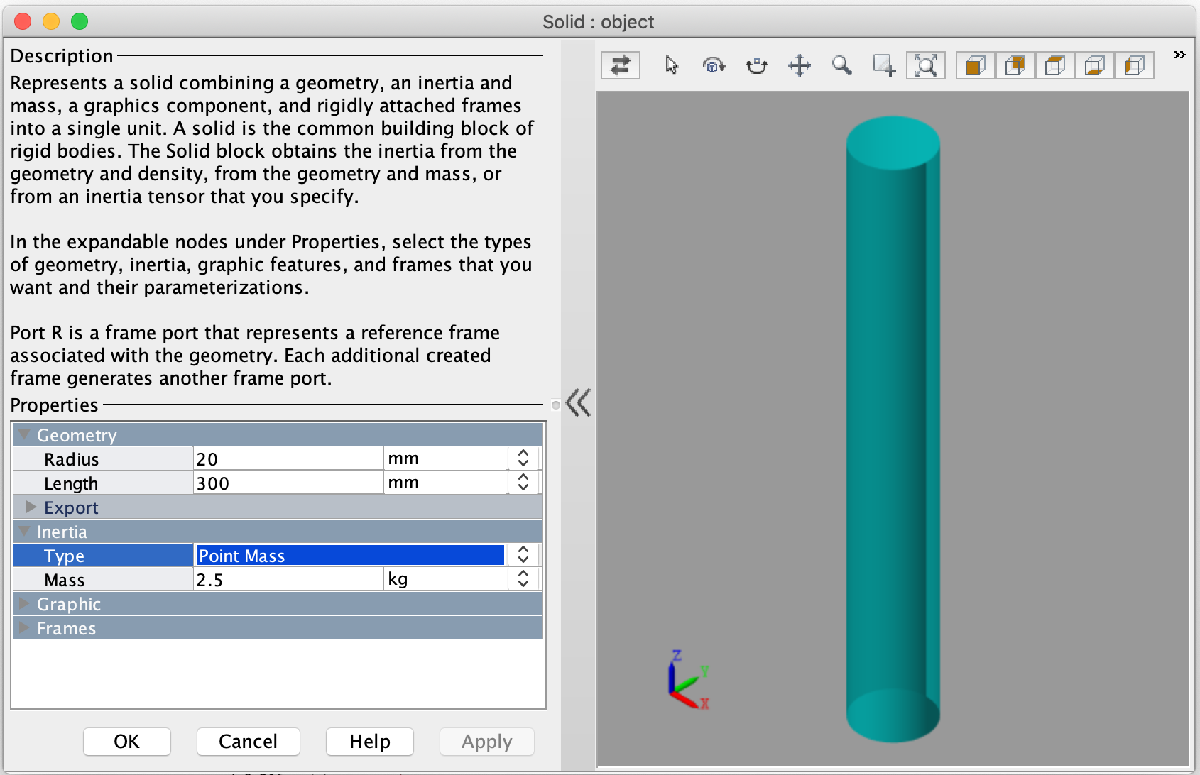

In the example the mass has been set to 1kg, and d has been chosen to be 0.01m. Therefore, k = (1*9.81)/0.01= 981 N/m. The coefficients can be entered by double clicking on the ClawBot block. You may notice that k has been scaled up from this calculated value, which is to prevent slipping.

### 4.2 Damping

The damping coefficient in the example has been set to critically damp the system and stop oscillations. The damping ratio equation c/m = 2*zeta*Wn can be used to calculate the damping coefficient, c, where m is the mass, zeta is the damping ratio and Wn is the natural frequency. Zeta is equal to 1 for critical damping and Wn = sqrt(k/m), therefore c = 2*sqrt(k*m) = 2*sqrt(981*1) = 62.6 Ns/m. Don't forget to multiply this by the square root of the scale factor used for the stiffness. 

### 4.3 Additional Modelling Points

The environment subsystem is a good example of how to go about modelling contact forces between bodies. 

- You can see that gravity has been applied to the object only, in order to speed up the running time. 

- A rigid transform has been used to translate the object to a desired location. 

- Instead of using a 6-DOF joint to separate the object from the rest of the world frame, a Cartesian joint with internal mechanics has been used. This ensures that the object doesn’t receive an impulse immediately upon being touched. Double clicking on the cartesian joint will show the small stiffnesses and damping coefficients which have been applied. 

### 4.4 Example

### 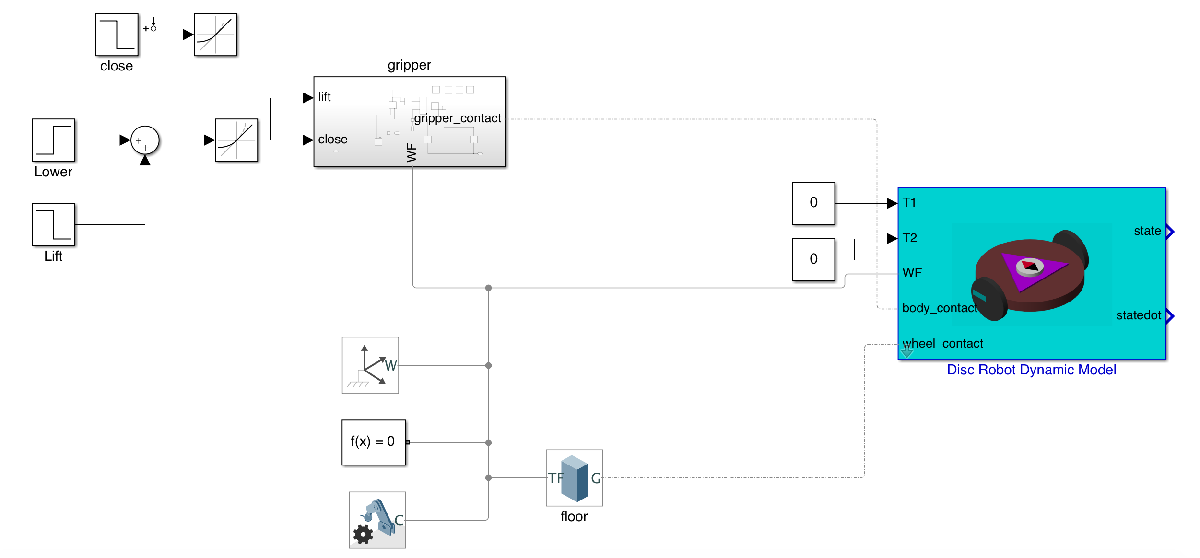

open_system("Contact_modelling")
 

This example demonstrates an alternative approach to contact modelling a pick-and-place system, this time the function being to lift a disc robot. Explore the model to familiarise yourself with the internal mechanics and functionality. Try adjusting the stiffness and damping coefficients to observe the corresponding effect on the grip. 

### 4.5 Task 4

open_system("Unit 4/Task4.slx")

This model will be familiar from the previous unit, except in this version the mass of the cylinder has been changed from 1kg to 2.5kg. Using your knowledge from this unit, calculate the appropriate damping and stiffness coefficients needed to pick up the cylinder, and input them into the model. Observe the behaviour of the system when the coefficients are set too high or too low. 

Check your coefficient values here once you have an answer. 

"0"